%clear all
% EMTAB4321 data set
dat1 = table2array(readtable("EMTAB4321/Pheno.txt"));
% convert 'noprogression/progression' into boolean
class1 = strcmpi(dat1(:,5),'progression');

% GSE13507 data set 
dat2 = table2array(readtable("GSE13507/Pheno.txt"));
class2 = strcmpi(dat2(:,5),'progression');

% GSE32894
dat3 = table2array(readtable("GSE32894/Pheno.txt"));
class3 = strcmpi(dat3(:,5),'progression');

% combine all three labels
class= [class1', class2', class3']';

clearvars class1 class2 class3 dat1 dat2 dat3

% import gene expression data
feature1 = readtable("EMTAB4321/Expr.txt");
feature2 = readtable("GSE13507/Expr.txt");
feature3 = readtable("GSE32894/Expr.txt");
% combine three data sets
T = innerjoin(feature1, innerjoin(feature2,feature3,"Keys","Var1"),"Keys","Var1");

% common genes across three data sets
% data1: 1 - 128; data2: 129 - 226; data3: 227 - 321
cgen = table2array(T(:,1)); %name
cfeature = table2array(T(:,2:end))'; % expression values
clearvars feature1 feature2 feature3 T

% k-fold cross validation setup
rng(6); % For reproducibility
cv = 3;
indices = crossvalind('Kfold',class,cv); %k-fold

%accu = []; sensi = []; speci = []; auroc = [];
N = 20; % lvl of filtering 
fpr5 = zeros(cv,31); tpr5 = zeros(cv,31); auroc5 = zeros(1,cv);


for i = 1:cv
    test = (indices == i);
    train = ~test;
    truey = class(test,:);
    
    rho = zeros(1,9854); %store correlation
    for j = 1:9854
        % (k-1)/k fraction of smaple
        rho(j) = corr(class(train,:), cfeature(train,j));
    end
    [~,index] = maxk(abs(rho),N);
    
    % build classifier 1 - logistic regression
    Mdl = fitglm(cfeature(train,index), class(train,:),'Distribution','binomial','Link','logit');
    prob1(:,i) = predict(Mdl, cfeature(test,index));
    [fpr1(:,i),tpr1(:,i),T1(:,i),auroc1(i)] = perfcurve(truey,prob1(:,i),1);
    t80_1(i) = find(tpr1(:,i) > .8,1)
    accuracy1(i) = sum(prob1(:,i) > T1(t80_1(i),i))/size(truey,1)
    
       
    %% build classifier 2 - naive bayes
    Mdl = fitcnb(cfeature(train,index), class(train,:));
    [~,prob] = predict(Mdl,cfeature(test,index));
    prob1(:,i) = prob(:,2); %class1
    [fpr2(:,i),tpr2(:,i),T2(:,i),auroc2(i)] = perfcurve(truey,prob1(:,i),1);
    
    % build classifier 3 - qda
    Mdl = fitcdiscr(cfeature(train,index), class(train,:),'DiscrimType','quadratic');
    [~,prob] = predict(Mdl,cfeature(test,index));
    prob1(:,i) = prob(:,2); %class1
    [fpr3(:,i),tpr3(:,i),T3(:,i),auroc3(i)] = perfcurve(truey,prob1(:,i),1);
    
    %% build classifier 4 - svm
    %[~,tpr4,fpr4,auroc4] = svm(cfeature,class,train,test,index);
    SVMModel = fitcsvm(cfeature(train,index),class(train,:),'Standardize',true);
    CompactSVMModel = compact(SVMModel);
    CompactSVMModel = fitPosterior(CompactSVMModel,cfeature(train,index),class(train,:));
    [~,prob] = predict(CompactSVMModel,cfeature(test,index));
    %prob1 = prob(:,2);
    %[fpr4,tpr4,T4,auroc4] = perfcurve(truey,prob1,1);
    prob1(:,i) = prob(:,2); %class1
    [fpr4(:,i),tpr4(:,i),T4(:,i),auroc4(i)] = perfcurve(truey,prob1(:,i),1);
    
    %% build classifier 5 - knn
    [~, tpr5(i,:),fpr5(i,:),auroc5(i)] = knn(cfeature,class,train,test,index,30);

end

t80_1 =     63    80    70


accuracy1 =     0.5701    0.7290    0.6355


t80_1 =     63    80    70


accuracy1 =     0.5701    0.7290    0.6355


t80_1 =     63    80    70


accuracy1 =     0.5701    0.7290    0.6355


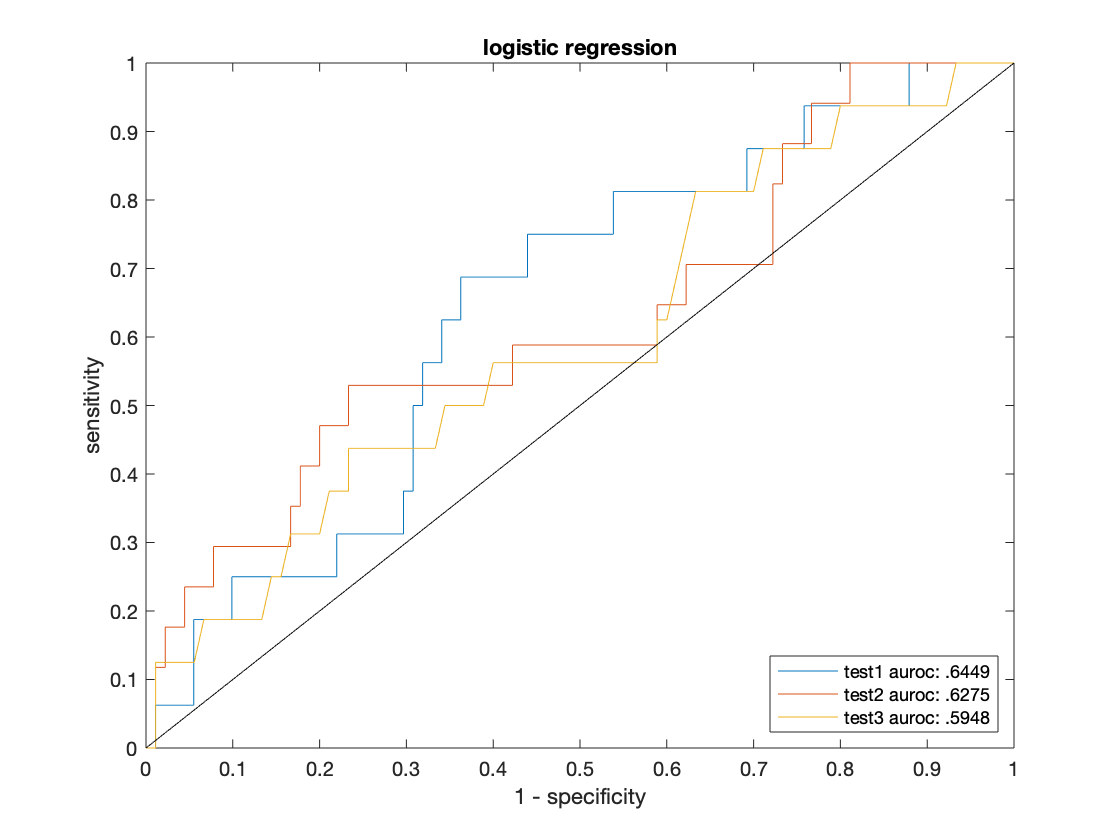

figure(1)
plot(fpr1(:,1),tpr1(:,1))
hold on 
plot(fpr1(:,2),tpr1(:,2))
hold on 
plot(fpr1(:,2),tpr1(:,3))
hold on 
plot(linspace(0,1),linspace(0,1),"Color",'k');
legend('test1 auroc: .6449','test2 auroc: .6275','test3 auroc: .5948','Location','southeast')
title('logistic regression')
xlabel('1 - specificity')
ylabel('sensitivity')
hold off

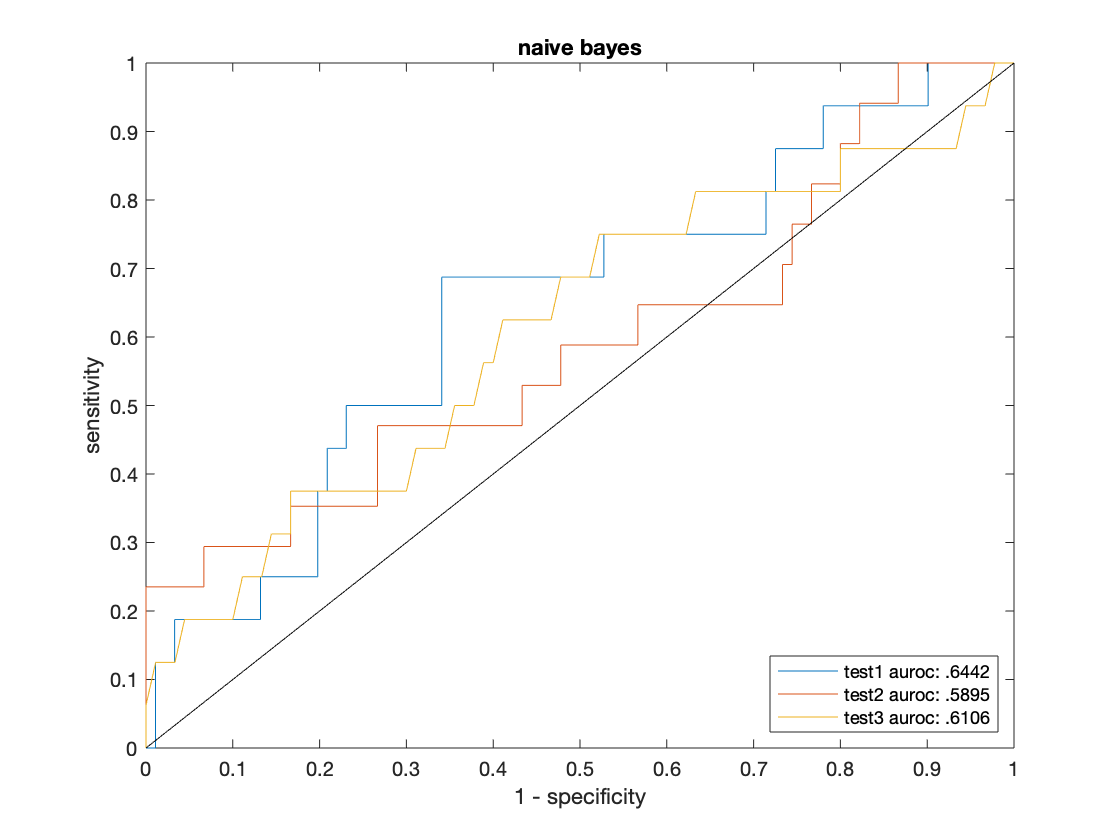

figure(2)
plot(fpr2(:,1),tpr2(:,1))
hold on 
plot(fpr2(:,2),tpr2(:,2))
hold on 
plot(fpr2(:,2),tpr2(:,3))
hold on 
plot(linspace(0,1),linspace(0,1),"Color",'k');
legend('test1 auroc: .6442','test2 auroc: .5895','test3 auroc: .6106','Location','southeast')
title('naive bayes')
xlabel('1 - specificity')
ylabel('sensitivity')
hold off

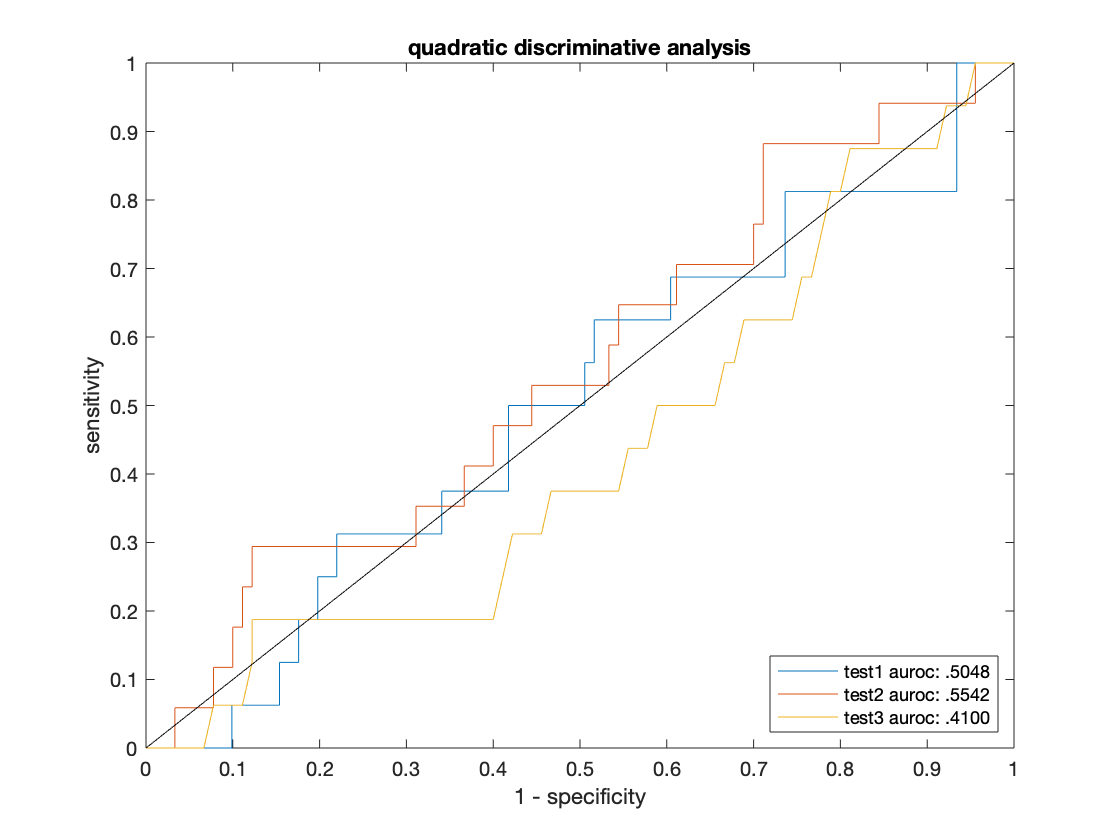

figure(3)
plot(fpr3(:,1),tpr3(:,1))
hold on 
plot(fpr3(:,2),tpr3(:,2))
hold on 
plot(fpr3(:,2),tpr3(:,3))
hold on 
plot(linspace(0,1),linspace(0,1),"Color",'k');
legend('test1 auroc: .5048','test2 auroc: .5542','test3 auroc: .4100','Location','southeast')
title('quadratic discriminative analysis')
xlabel('1 - specificity')
ylabel('sensitivity')
hold off

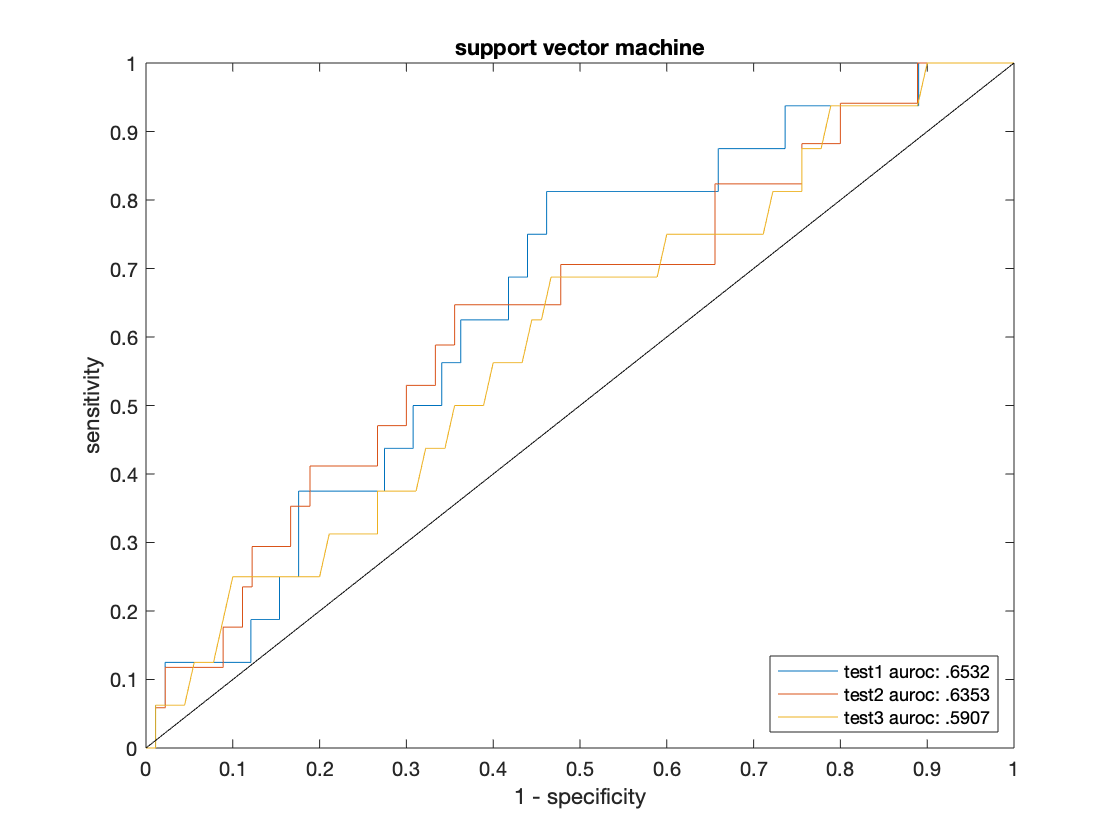

figure(4)
plot(fpr4(:,1),tpr4(:,1))
hold on 
plot(fpr4(:,2),tpr4(:,2))
hold on 
plot(fpr4(:,2),tpr4(:,3))
hold on 
plot(linspace(0,1),linspace(0,1),"Color",'k');
legend('test1 auroc: .6532','test2 auroc: .6353','test3 auroc: .5907','Location','southeast')
title('support vector machine')
xlabel('1 - specificity')
ylabel('sensitivity')

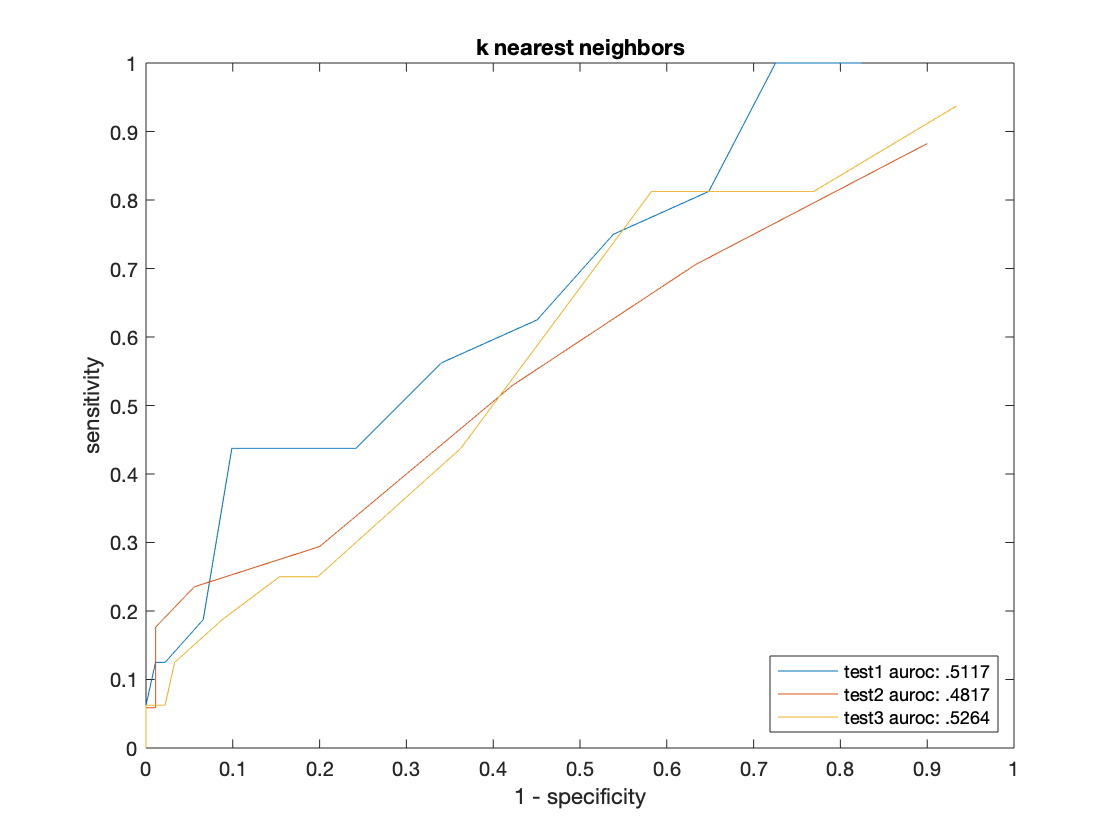

hold off 

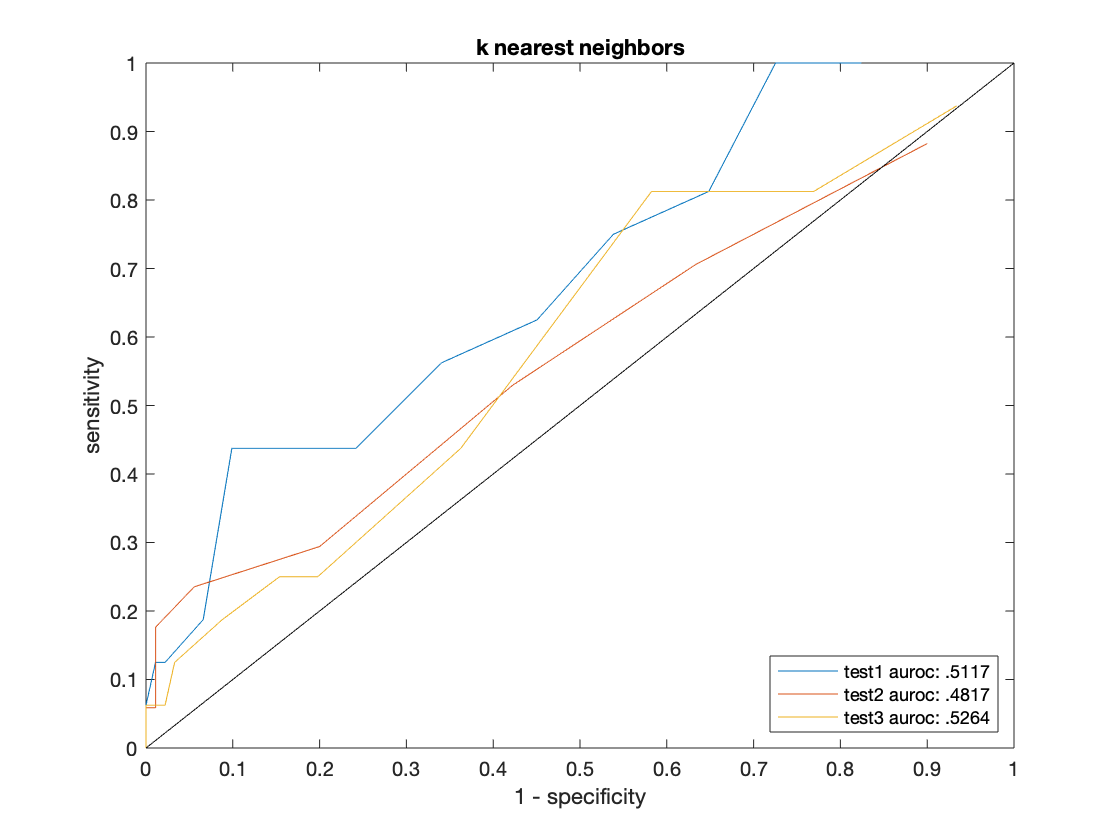

figure
plot(fpr5(1,:),tpr5(1,:))
hold on 
% legend('test1 auroc: .4725','Location','southeast')
% subplot(3,1,2)
plot(fpr5(2,:),tpr5(2,:));
hold on 
% legend('test2 auroc: .4582','Location','southeast')
% subplot(3,1,3);
plot(fpr5(3,:),tpr5(3,:))
hold on 
plot(linspace(0,1),linspace(0,1),"Color",'k');
legend('test1 auroc: .5117','test2 auroc: .4817','test3 auroc: .5264','Location','southeast')
title('k nearest neighbors')
xlabel('1 - specificity')
ylabel('sensitivity')

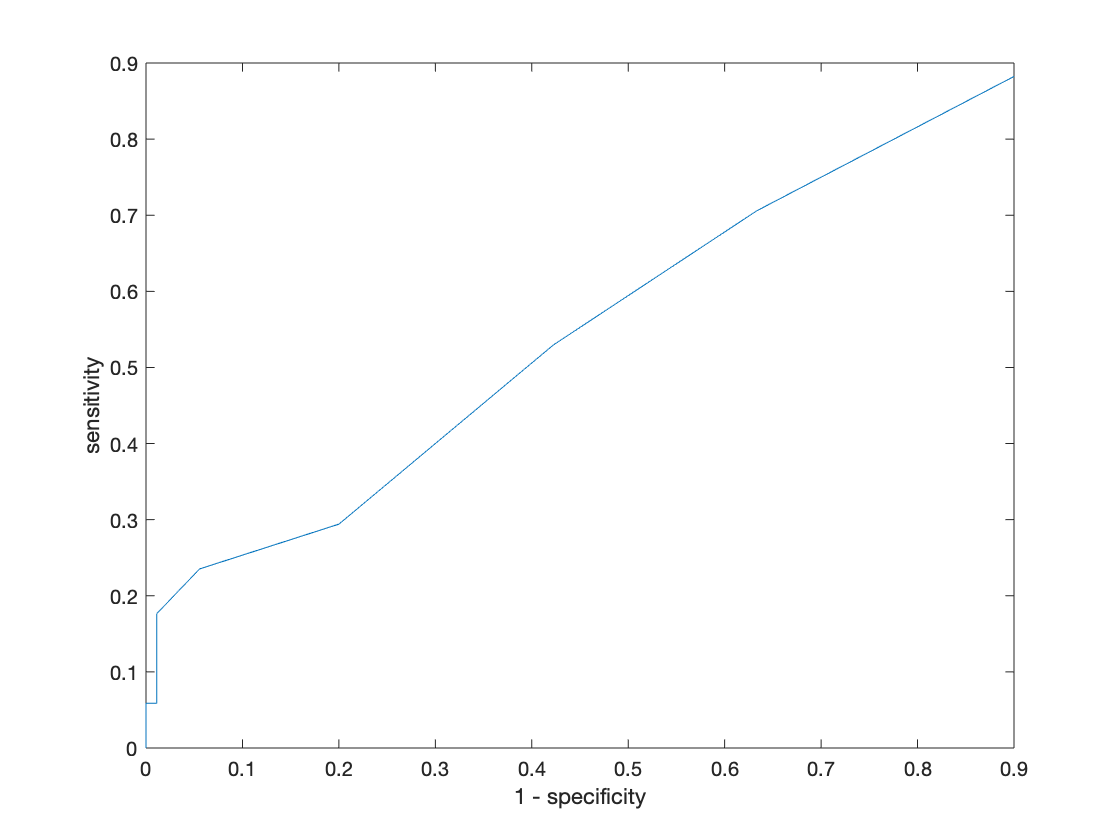


avgtpr1 = mean(tpr1,2);
avgtpr2 = mean(tpr2,2);
avgtpr3 = mean(tpr3,2);
avgtpr4 = mean(tpr4,2);
avgtpr5 = mean(tpr5);

avgfpr1 = mean(fpr1,2);
avgfpr2 = mean(fpr2,2);
avgfpr3 = mean(fpr3,2);
avgfpr4 = mean(fpr4,2);
avgfpr5 = mean(fpr5);

hold off

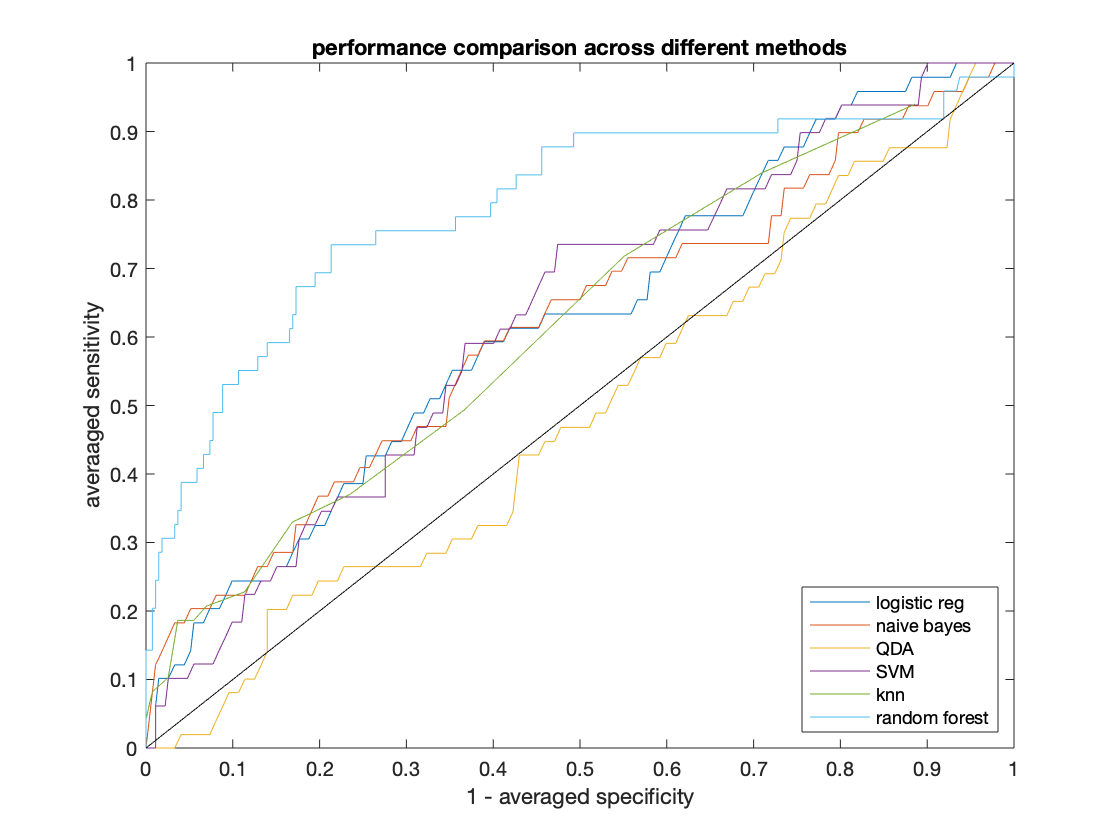

figure(6)
plot(avgfpr1,avgtpr1)
hold on 
plot(avgfpr2,avgtpr2)
hold on 
plot(avgfpr3,avgtpr3)
hold on 
plot(avgfpr4,avgtpr4)
hold on 
plot(avgfpr5,avgtpr5)
hold on 
plot(fpr_rf,tpr_rf)
hold on 
plot(linspace(0,1),linspace(0,1),"Color",'k');
%legend('logistic reg','naive bayes','SVM','knn','Location','southeast')
legend('logistic reg','naive bayes','QDA','SVM','knn','random forest','Location','southeast')
title('performance comparison across different methods')
xlabel('1 - averaged specificity')
ylabel('averaaged sensitivity')